# A few examples on how to use the Simscape battery library models through code

**WMG, University of Warwick**

W.D. Widanage 19/09/2021 (Turn the page)

## Introduction

This live editior script includes four examples, all based on the TSPMe model (the cell model can be replaced with the TECMD model from the library as well)

- 1C current discharge

- A power profile based discharge

- Simulating a series of events in succession

- Estimating Remaining-Useful-Energy and Time-to-Discharge

Tip: Run one section at a time rather than running the entire file.

## Eg. 1: A 1C discharge - the "Hello World" of a battery model

Simulate a standard 1C discharge from 100% SoC until Vmin

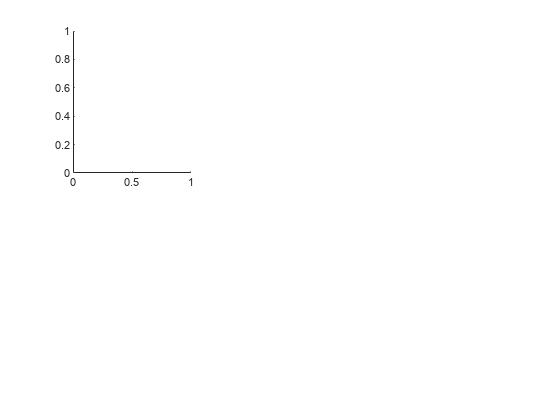

Unrecognized function or variable 'cn'.

Error in gettingStarted>plot_TSPME_States (line 282)
    plot(rn_SI,cn(tt,:),'. -')

clear, clc
simuLinkMdlStr = 'TSPMe_Prototype';                                                     % Specify the simulink file name (without the file extension)
Vmax = 4.2;                                                                             % Set upper cut-off voltage [V]
Vmin = 2.5;                                                                             % Set lower cut-off voltage for terminating discharge [V]

modelProp = Simulink.SimulationInput(simuLinkMdlStr);                                   % Create an instance of a Matlab SimulationInput class to simulate

% CC Discharge
appCurr = -5*timeseries(1,0,'Name',"I");                                                % Generate 1C input current as a timeseries object (1C := 5A) [A]
modelProp = modelProp.setExternalInput('appCurr');                                      % Set the external input to the model
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/TSPMe'],'z0',num2str(1));     % Set initial cell SoC to 100%
modelProp = modelProp.setModelParameter('StopTime','inf','SaveState','on','SaveOutput','on','SaveFinalState','on','FinalStateName','OperPoint'); % Set simuation options
simOut_D = sim(modelProp);                                                              % Simulate the "modelProp" object with above specifications

% Once simulation is complete plot the key variables I/V/T, SoC, electrode potentials at
% the current collector and OCV
plot_TSPME_Results(simOut_D)

% Once simulation is complete plot spatial concentrations and potentials (plotting animation can be a bit slow!)
plot_TSPME_States(simOut_D,simuLinkMdlStr)

## Eg. 2: Applying a power profile as input

Apply a constant power discharge with a cell initial soc of 70%, intial cell temperature of 10degC and ambient temperature of 25degC 

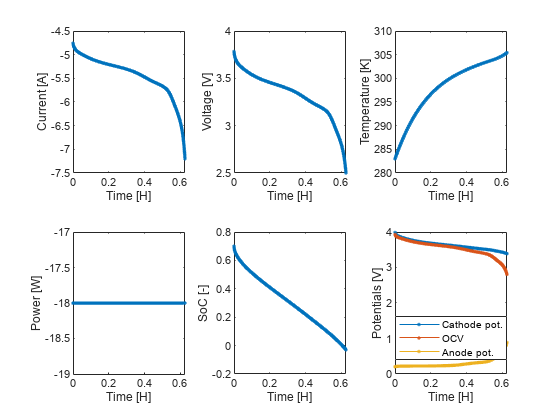

clear, clc
simuLinkMdlStr = 'TSPMe_Prototype';                                                                             % Specify the simulink file name (without the file extension)
Vmax = 4.2;                                                                                                     % Set upper cut-off voltage [V]
Vmin = 2.5;                                                                                                     % Set lower cut-off voltage for terminating discharge [V]

modelProp = Simulink.SimulationInput(simuLinkMdlStr);                                                           % Create an instance of a Matlab SimulationInput class to simulate


% Constant power discharge
appPow = -18*timeseries(1,0,'Name',"P");                                                                        % Generate an input power profile as a timeseries object [W]
modelProp = modelProp.setExternalInput('appPow');                                                               % Set an external input to the model
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','2');                   % Set the "Electrical Source" block to "2" for a power input. Options: "0": Current, "1": Voltage, "2": Power

% Changing any intial conditions if needed:
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/TSPMe'],'z0',num2str(0.7));                           % Initial cell SoC, let's assume 70%
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Temperature Source'],'temperature',num2str(298));     % Ambient temperature [K], let's assume room temperature
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/TSPMe'],'T0',num2str(283));                           % Initial cell temperature [K], let's assume 283K (10degC)

modelProp = modelProp.setModelParameter('StopTime','inf','SaveState','on','SaveOutput','on','SaveFinalState','on','FinalStateName','OperPoint'); % Set simuation options

simOut_P = sim(modelProp);                                                                                      % Simulate the "modelProp" object with the above specifications

% Once simulation is complete plot the key variables I/V/T, SoC, electrode potentials at
% the current collector and OCV
plot_TSPME_Results(simOut_P)

## Eg. 3: Simulate a series of events: CP -> Rest -> CCCV

This is an example that performs a series of events while changing the input from a power profile, to a rest and then to a current profile. The series of events are:

- constant **power** discharge, 

- followed by a **rest period** 

- and then a **CCCV charge** as the input. 

clear, clc
simuLinkMdlStr = 'TSPMe_Prototype';                         % Specify the simulink file name (without the file extension)

modelProp = Simulink.SimulationInput(simuLinkMdlStr);       % Create an instance of a Matlab SimulationInput class to simulate

Vmax = 4.2;                                                 % Set upper cut-off voltage to terminate CC charge [V]
Vmin = 2.5;                                                 % Set lower cut-off voltage to terminate CP discharge [V]

evtList = ["CP_D","Rest","CC_C","CV"];                      % Define the sequence of events

for ee = 1:length(evtList)
    if evtList(ee) == "CP_D"
        appCurr = -18*timeseries(1,0,'Name',"I");           % CP discharge [W] 
        modelProp = modelProp.setExternalInput('appCurr');  % Set an external input to the model
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','2');   % Set the "Electrical Source" block to '0' for a current input. Options: '0': Current, '1': Voltage, '2': Power
        tEnd = 'inf';                                       % Set simulation time to 'inf'
    elseif evtList(ee) == "Rest"
        tRest = 3600;                                       % Rest time [s]
        appCurr = 0*timeseries(1,0,'Name',"I");             % Set input current to 0A [A]
        modelProp = modelProp.setExternalInput('appCurr');  % Set an external input to the model
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','0');   % Set the "Electrical Source" block to '0' for a current input. Options: '0': Current, '1': Voltage, '2': Power
        tEnd = num2str(simOut_E(ee-1).OperPoint.snapshotTime + tRest); % Update the simualtion end time from previous event endtime
    elseif evtList(ee) == "CC_C"
        appCurr = 5/3*timeseries(1,0,'Name',"I");            % C/3 charge [A] (1C := 5A)
        modelProp = modelProp.setExternalInput('appCurr');   % Set an external input to the model
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','0');   % Set the "Electrical Source" block to '0' for a current input. Options: '0': Current, '1': Voltage, '2': Power
        tEnd = 'inf';                                        % Set simulation time to 'inf'
    elseif evtList(ee) == "CV"
        appVol = Vmax*timeseries(1,0,'Name',"V");            % Constant voltage [V]
        modelProp = modelProp.setExternalInput('appVol');    % Set an external input to the model
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','1');   % Set the "Electrical Source" block to '1' for a voltage input. Options: '0': Current, '1': Voltage, '2': Power
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Terminate CV mode/enableCV'],'value',num2str(1));     % Enable CV mode 
        tEnd = 'inf';                                        % Set simulation time to 'inf'
    end

    if ee > 1
        x0 = simOut_E(ee-1).OperPoint;
        modelProp = modelProp.setInitialState(x0);
    end
    modelProp = modelProp.setModelParameter('StopTime',tEnd,'SaveState','on','SaveOutput','on','SaveFinalState','on','FinalStateName','OperPoint');
    simOut_E(ee,1) = sim(modelProp);
end

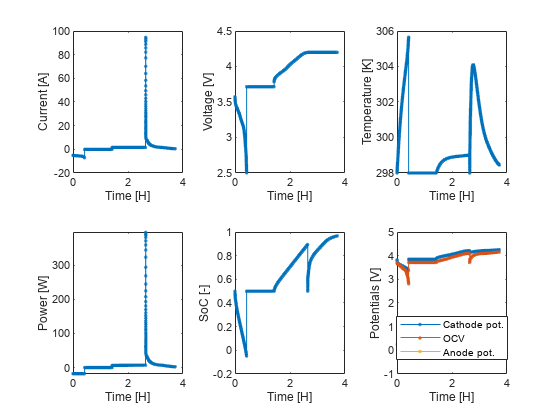


% Once simulation is complete plot the key variables I/V/T, SoC, electrode potentials at
% the current collector and OCV
plot_TSPME_Results(simOut_E)

## Eg. 4: Compute Remaning Useful Energy and Time-To-Discharge maps with TSPMe

Use the TSPMe model to calculate the Remaining Useful Energy (RUE) and Time to Discharge (TTD) of the cell as a function of different starting SoCs, starting temperatures and discharge powers

clear, clc
simuLinkMdlStr = 'TSPMe_Prototype';             % Specify the simulink file name (without the file extension)

nomE = 17.5;                                    % Nominal cell (LG M50) energy [Wh] @ 25degC
Vmax = 4.2;                                     % Set upper cut-off voltage
Vmin = 2.5;                                     % Set lower cut-off voltage for RUE/TTD

lowestSoC = 0.05;                               % Lowest starting SoC for RUE
highestSoC = 1;                                 % Highest starting SoC for RUE
nZ = 6;                                         % Number of SoC points
z0 = linspace(lowestSoC,highestSoC,nZ);         % Initial cell SoCs for RUE [-]

lowestPow = -10;                                % Lowest discharge power, negative for discharge [W]
highestPow = -40;                               % Highest discharge power, negative for discharge [W]
nP = 6;                                         % Number of different input discarge power rates
P = linspace(lowestPow,highestPow,nP);          % Discharge powers [W]

lowestAmbTemp = 10;                             % Lowest starting ambient temperature [degC]
highestAmbTemp = 40;                            % Highest starting ambient temperature [degC]
nT = 4;                                         % Number of temperautre points
ambTemp = linspace(lowestAmbTemp,highestAmbTemp,nT) + 273;   % Ambient temperatures for RUE [K]

%% Parameters: Thermal
T0 = ambTemp;                                   % Initial cell temperature [K] -  In these simulations the initial cell temperature is identical to the ambient temperautre set


% A unit amplitude power timeseries object
powVec = timeseries(1,0,'Name',"P");

cntr = 0;
for jj = 1:nT
    for ii = 1:nP
        for zz = 1:nZ
            cntr = cntr + 1;

            %% Create a model SimulationInput object
            modelProp(cntr) = Simulink.SimulationInput(simuLinkMdlStr);

            % Set input
            ps = powVec*P(ii); ps.Name = "power";
            modelProp(cntr) = modelProp(cntr).setExternalInput('ps');
            modelProp(cntr) = modelProp(cntr).setVariable('ps',ps,'Workspace',simuLinkMdlStr);
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','2');   % Set the "Electrical Source" block to '2' for a power input. Options: '0': Current, '1': Voltage, '2': Power


            % Set TSPMe initial conditions
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/Temperature Source'],'temperature',num2str(ambTemp(jj)));
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/TSPMe'],'T0',num2str(T0(jj)));
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/TSPMe'],'z0',num2str(z0(zz)));

            % Simulation run time settings
            modelProp(cntr) = modelProp(cntr).setModelParameter('StopTime','inf','SaveState','on','SaveOutput','on','SaveOperatingPoint','on', ...
                                                                'SaveFinalState','on','FinalStateName','OperPoint');
        end
    end
end

%% Simulate in parallel using parsim
tic
simOut = parsim(modelProp,'TransferBaseWorkspaceVariables',"on","ShowProgress","on");
toc

#### Calculate Time-to-Discharge (TTD) and Remaining Useful Energy (RUE)

for ii = 1:cntr
    mdlCurr = find(simOut(ii).logsout,'I');
    mdlVol = find(simOut(ii).logsout,'V');
    appP = min(mdlCurr.Values.*mdlVol.Values);
    TTDVec(ii,1) = max(mdlCurr.Values.Time)/60;     % Time to discharge in minutes
    RUEVec(ii,1) = -appP *TTDVec(ii)/60;            % RUE in [Wh] - Integration simplifies to a multiplcation because the discharge power is a constant
end

% Reshape TTD and RUE into nZ x nP x nT
TTD = reshape(TTDVec,nZ,nP,nT);
RUE = reshape(RUEVec,nZ,nP,nT)/nomE*100;            % Relative RUE

% Plot TTD and RUE vs SoC for each ambient temperature
for tt = 1:nT
    figure
    subplot(1,2,1)
    plot(z0,RUE(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('SoC [-]'); ylabel('RUE [%]'); legend(string(-P)+"W",'Location',"best")
    subplot(1,2,2)
    plot(z0,TTD(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('SoC [-]'); ylabel('TTD [min]'); legend(string(-P)+"W",'Location',"best")
end

% Plot TTD and RUE vs discharge power for each ambient temperature
RUE_P = permute(RUE,[2,1,3]);        % nP, nZ, nT
TTD_P = permute(TTD,[2,1,3]);        % nP, nZ, nT
for tt = 1:nT
    figure
    subplot(1,2,1)
    plot(-P,RUE_P(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('Power [W]'); ylabel('RUE [%]'); legend(["SoC:" + string(z0)],'Location',"best")
    subplot(1,2,2)
    plot(-P,TTD_P(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('Power [W]'); ylabel('TTD [min]'); legend(["SoC:" + string(z0)],'Location',"best")
end

## Function definitions

#### **Function to plot key variables **

function plot_TSPME_Results(simOut)
% Initialise variables
time = []; curr = []; vol = []; temp = []; pow = []; soc = []; pots = [];

for ss = 1:length(simOut)
    time = [time;simOut(ss).tout/3600];                 % Simulatiom time [H]
    mdlCurr = find(simOut(ss).logsout,'I');             % Current [A]
    mdlVol = find(simOut(ss).logsout,'V');              % Voltage [V]
    mdlTemp = find(simOut(ss).logsout,'T');             % Temperature [K]
    mdlPow = mdlCurr.Values.*mdlVol.Values;         % Power [W]
    mdlSoC = find(simOut(ss).logsout,'SoC');            % SoC [-]
    mdlPots = find(simOut(ss).logsout,'Potentials');    % Potentials [V]
    curr = [curr; mdlCurr.Values.Data]; vol = [vol; mdlVol.Values.Data]; temp = [temp; mdlTemp.Values.Data]; pow = [pow; mdlPow.Data]; soc = [soc; mdlSoC.Values.Data]; pots = [pots; mdlPots.Values.Data];
end

tiledlayout(2,3);

ax(1) = nexttile;
plot(time,curr,'. -');
xlabel('Time [H]'); ylabel('Current [A]')

ax(2) = nexttile;
plot(time,vol,'. -');
xlabel('Time [H]'); ylabel('Voltage [V]')

ax(3) = nexttile;
plot(time,temp,'. -');
xlabel('Time [H]'); ylabel('Temperature [K]')

ax(4) = nexttile;
plot(time,pow,'. -');
ylim([min(pow)-1,max(pow)+1])
xlabel('Time [H]'); ylabel('Power [W]')

ax(5) = nexttile;
plot(time,soc,'. -');
xlabel('Time [H]'); ylabel('SoC [-]')

ax(6) =  nexttile;
plot(time,pots,'. -');
xlabel('Time [H]'); ylabel('Potentials [V]'); legend('Cathode pot.', 'OCV', 'Anode pot.','Location',"best")

linkaxes(ax,'x')
end

#### **Function to plot distributed variables**

function plot_TSPME_States(simOut,simuLinkMdlStr)
for ll = 1:numElements(simOut.xout)
    strLbl = extractAfter(simOut.xout{ll}.Name,[simuLinkMdlStr,'.TSPMe.']);
    if matches(strLbl,"cn"); cn = simOut.xout{ll}.Values.Data; end              % Negative electrode concentration [mol/m^3]
    if matches(strLbl,"ce"); ce = simOut.xout{ll}.Values.Data; end              % Electrolyte concentration [mol/m^3]
    if matches(strLbl,"cp"); cp = simOut.xout{ll}.Values.Data; end              % Positve electrode concentration [mol/m^3]
    if matches(strLbl,"Phin_hat"); Phi_n = simOut.xout{ll}.Values.Data; end     % Negative electrode potential [V]
    if matches(strLbl,"Phie_hat"); Phi_e = simOut.xout{ll}.Values.Data; end     % Electrolyte potential [V]
    if matches(strLbl,"Phip_hat"); Phi_p = simOut.xout{ll}.Values.Data; end     % Positve electrode potential [V]
end

Rn = simscape.Value(str2num(get_param([simuLinkMdlStr,'/TSPMe'],'Rn')),get_param([simuLinkMdlStr,'/TSPMe'],'Rn_unit'));  % Negative particle radius
Rp = simscape.Value(str2num(get_param([simuLinkMdlStr,'/TSPMe'],'Rp')),get_param([simuLinkMdlStr,'/TSPMe'],'Rp_unit'));  % Positve particle radius

Ln = simscape.Value(str2num(get_param([simuLinkMdlStr,'/TSPMe'],'Ln')),get_param([simuLinkMdlStr,'/TSPMe'],'Ln_unit'));  % Negative electrode thickness
Ls = simscape.Value(str2num(get_param([simuLinkMdlStr,'/TSPMe'],'Ls')),get_param([simuLinkMdlStr,'/TSPMe'],'Ls_unit'));  % Seperator thickness
Lp = simscape.Value(str2num(get_param([simuLinkMdlStr,'/TSPMe'],'Lp')),get_param([simuLinkMdlStr,'/TSPMe'],'Lp_unit'));  % Positive electorde thickness

cpmax = simscape.Value(str2num(get_param([simuLinkMdlStr,'/TSPMe'],'cp_max')),get_param([simuLinkMdlStr,'/TSPMe'],'cp_max_unit'));  % Maximum negative electrode concentration

L = Lp + Ls + Ln;               % Total cell thickness
lp = value(Lp/L,'1');
ls = value(Ls/L,'1');
ln = value(Ln/L,'1');

Rn_SI = value(Rn,'m');
Rp_SI = value(Rp,'m');
Ln_SI = value(Ln,'m');
Lp_SI = value(Lp,'m');
L_SI = value(L,'m');
cp_max_SI = value(cpmax,'mol/m^3');

s6 = [-1	-0.809016994374948	-0.309016994374947	0.309016994374947	0.809016994374948	1];                                                     % Six collocation points used in TSPMe on standard interval [-1,1]                                                                                                                                   % Three collocation points on standard interval [-1,1]
s10 = [-1	-0.939692620785908	-0.766044443118978	-0.5	-0.173648177666930	0.173648177666930	0.5	0.766044443118978	0.939692620785908	1]; % Ten collocation points used in TSPMe on standard interval [-1,1]

xn = ln*(1+s10)/2;           % -ve electrode domain collocation points on interval [0,ln]
xs = ln + ls*(1+s6)/2;       % Separator domain collocation points on interval [ln,ln+ls]
xp = (ln+ls) + lp*(1+s10)/2; % +ve electrode domain collocation points on interval [ln+ls,lp]

xn_SI = xn*double(Ln_SI);                      % Negative electrode domain [0, Ln]
xp_SI = xp*double(Lp_SI);                      % Positive electrode domain [Ln+Ls, Lp]
x_SI = [xn,xs(2:end-1),xp]*double(L_SI);       % Full electrode domain [0,L]
rn_SI = (1+s10)/2*double(Rn_SI);               % Radial domain collocation points on interval [0,Rn]
rp_SI = (1+s10)/2*double(Rp_SI);               % Radial domain collocation points on interval [0,Rp]

time = simOut.tout;
for tt = 1:70:length(time)
    tiledlayout(2,3);

    nexttile
    plot(rn_SI,cn(tt,:),'. -')
    xlabel('x [m]'); ylabel('c_n [mol/m^3]'); title('-ve')
    ylim([0,double(cp_max_SI)])

    nexttile
    plot(x_SI,ce(tt,:),'. -')
    xlabel('x [m]'); ylabel('c_e [mol/m^3]'); title('Electrolyte')
    ylim([0,max(ce(:))])

    nexttile
    plot(rp_SI,cp(tt,:),'. -')
    xlabel('x [m]'); ylabel('c_p [mol/m^3]'); title('+ve')
    ylim([0,double(cp_max_SI)])

    nexttile
    plot(xn_SI,Phi_n(tt,:),'. -')
    xlabel('xn [m]'); ylabel('\Phi_n [V]')
    ylim([min(Phi_n(:)),max(Phi_n(:))]); title('-ve')

    nexttile
    plot(x_SI,Phi_e(tt,:),'. -')
    xlabel('x [m]'); ylabel('\Phi_e [V]'); title('Electrolye')
    ylim([min(Phi_e(:)),max(Phi_e(:))])

    nexttile
    plot(xp_SI,Phi_p(tt,:),'. -')
    xlabel('xp [m]'); ylabel('\Phi_p [V]')
    ylim([min(Phi_p(:)),max(Phi_p(:))]); title('+ve')

    drawnow limitrate
end

end